# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 5;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp5'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.4453   -0.4788   -0.4836   -0.4932   -0.5315   -0.4214   -0.4357   -0.4741   -0.4453   -0.4549   -0.4405   -0.4022   -0.4022   -0.3831   -0.4693   -0.4549   -0.4310   -0.4022   -0.3735   -0.5267   -0.4597   -0.4501   -0.4214   -0.3974   -0.4453   -0.4932   -0.4549   -0.5124   -0.3783   -0.4549   -0.3974   -0.4070   -0.4549   -0.4166   -0.4836   -0.4118   -0.4788   -0.4549   -0.4262   -0.3831   -0.4405   -0.4310   -0.4166   -0.4357   -0.4836   -0.3974   -0.4262   -0.4932   -0.4693   -0.4932
   -0.1676   -0.1724   -0.1724   -0.1293   -0.2298   -0.1341   -0.1724   -0.2155   -0.1772   -0.1389   -0.1293   -0.1724   -0.1293   -0.2394   -0.2059   -0.1724   -0.1772   -0.1580   -0.2346   -0.2251   -0.1628   -0.1197   -0.2059   -0.1628   -0.1772   -0.2107   -0.1628   -0.1149   -0.1963   -0.1484   -0.1867   -0.1772   -0.1676   -0.1437   -0.1628   -0.1197   -0.1389   -0.2011   -0.1676   -0.1293   -0.1293   -0.1867   -0.1628   -0.1197   -0.1149   -0.2203   -0.2346   -0.1628   -0.1915   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

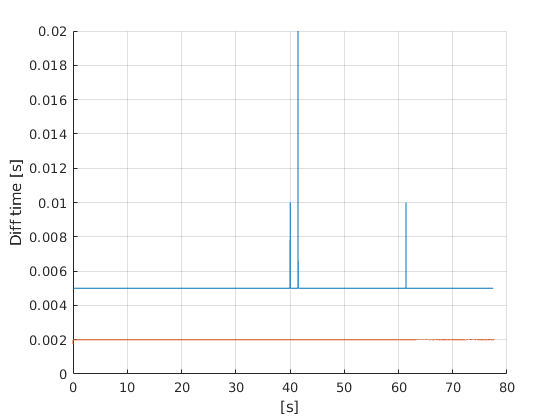

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

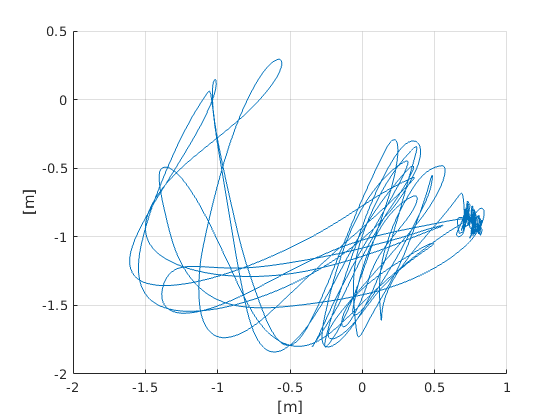

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

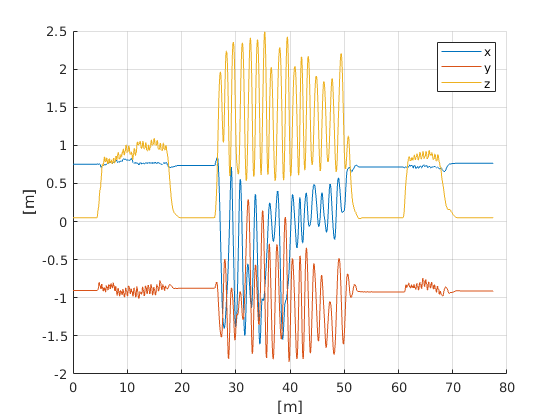

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

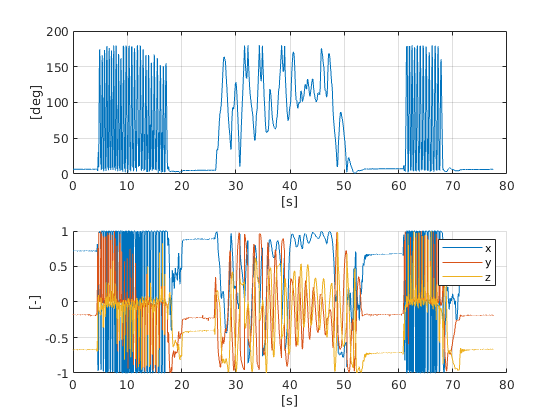

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN   -0.1156    0.1107    0.0453   -0.0492    0.0052   -0.0380   -0.0280    0.0430    0.0025    0.0206    0.0699   -0.0898   -0.0458    0.0954    0.0493    0.0263   -0.0602   -0.0180   -0.0052   -0.0458    0.0126   -0.0247   -0.0129    0.0514   -0.0072   -0.0377    0.0037   -0.0165   -0.0113    0.0817    0.0295   -0.0629    0.0273    0.0256   -0.0384    0.0505   -0.0342   -0.0336   -0.0166   -0.0241    0.1169   -0.0335   -0.0738    0.0300    0.0286    0.0453   -0.0697   -0.0155    0.0408
       NaN   -0.0137   -0.0010   -0.0035   -0.0196   -0.0061   -0.0125   -0.0115    0.0061    0.0083    0.0029   -0.0088   -0.0216   -0.0089    0.0094    0.0224    0.0170   -0.0288   -0.0132    0.0246    0.0097    0.0017   -0.0104   -0.0037    0.0006   -0.0057    0.0009    0.0136   -0.0016   -0.0073    0.0044    0.0172   -0.0293   -0.0227    0.0388    0.0126   -0.0164   -0.0013    0.0071   -0.0087    0.0117    0.0130   -0.0314   -0.0063    0.0222    0.0029   -0.0050   -0.0167    0.01

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

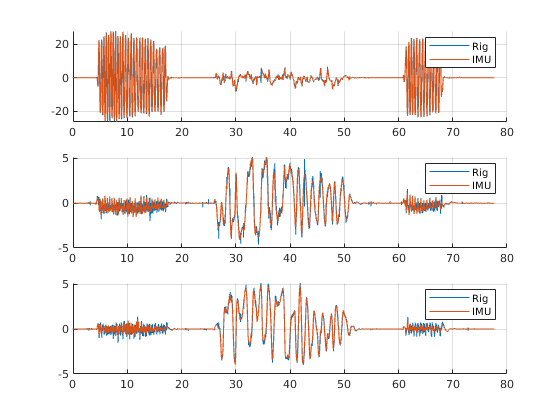

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

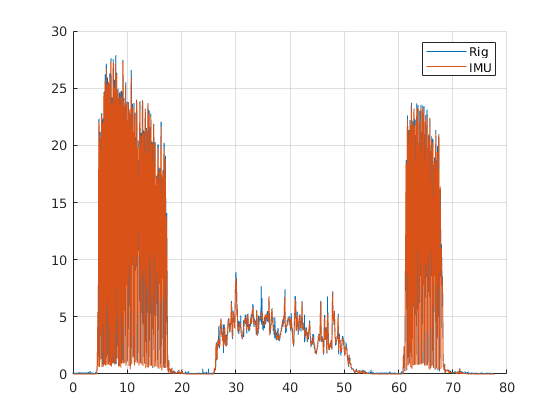

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0174    0.0174    0.0176    0.0174    0.0176    0.0176    0.0177    0.0177    0.0178    0.0177    0.0177    0.0176    0.0178    0.0179    0.0178    0.0177    0.0176    0.0176    0.0179    0.0177    0.0177    0.0176    0.0176    0.0178    0.0177    0.0177    0.0177    0.0177    0.0176    0.0177    0.0177    0.0177    0.0175    0.0180    0.0177    0.0176    0.0176    0.0177    0.0176    0.0177    0.0177    0.0176    0.0176    0.0179    0.0176    0.0177    0.0176    0.0177    0.0178    0.0175
    0.0859    0.0846    0.0848    0.0857    0.0852    0.0852    0.0853    0.0848    0.0850    0.0852    0.0850    0.0854    0.0857    0.0845    0.0853    0.0855    0.0857    0.0858    0.0851    0.0856    0.0851    0.0851    0.0852    0.0849    0.0851    0.0854    0.0850    0.0850    0.0851    0.0849    0.0849    0.0857    0.0852    0.0850    0.0855    0.0853    0.0851    0.0858    0.0848    0.0855    0.0846    0.0852    0.0858    0.0849    0.0851    0.0852    0.0853    0.0856    

for i = 1:3

imu_unit_tot =     0.0023    0.0009    0.0007    0.0019    0.0015    0.0013    0.0011    0.0004    0.0017    0.0011    0.0017    0.0030    0.0009    0.0029    0.0027    0.0011    0.0020    0.0021    0.0013    0.0026    0.0021    0.0018    0.0020    0.0009    0.0032    0.0004    0.0013    0.0016    0.0015    0.0025    0.0015    0.0003    0.0020    0.0009    0.0015    0.0018    0.0012    0.0021    0.0009    0.0008    0.0032    0.0015    0.0002    0.0028    0.0013    0.0020    0.0018    0.0010    0.0026    0.0011
    0.0398    0.0397    0.0399    0.0431    0.0413    0.0407    0.0401    0.0413    0.0420    0.0407    0.0399    0.0396    0.0399    0.0408    0.0406    0.0406    0.0410    0.0405    0.0409    0.0407    0.0418    0.0414    0.0394    0.0403    0.0421    0.0404    0.0410    0.0405    0.0402    0.0408    0.0412    0.0402    0.0414    0.0400    0.0405    0.0405    0.0402    0.0424    0.0402    0.0416    0.0407    0.0406    0.0417    0.0395    0.0403    0.0400    0.0403    0.0395    

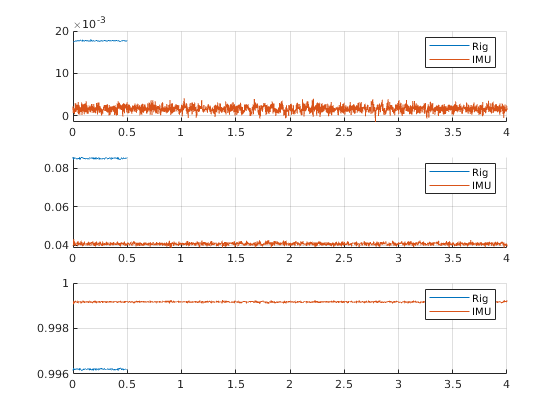

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 7.757e-04 / 1.000e-12
2/100: tol: 5.309e-12 / 1.000e-12
3/100: tol: 8.432e-18 / 1.000e-12


R_stationary_rig_mean =     0.9967   -0.0795    0.0177
    0.0778    0.9933    0.0852
   -0.0243   -0.0835    0.9962


e_R = 	1.0e+-3 *

   -0.7459    0.6011    0.4277   -0.5103   -0.0241   -0.0004   -0.0739    0.3898    0.2109   -0.0467    0.1776   -0.2582   -0.5156    0.6591   -0.0492   -0.3056   -0.5614   -0.5817    0.0651   -0.3912    0.0998    0.0581   -0.0307    0.3212    0.1043   -0.1958    0.1768    0.1759    0.1336    0.3440    0.2494   -0.4787   -0.0644    0.1776   -0.3195   -0.1110    0.0617   -0.6055    0.4036   -0.2742    0.5767   -0.0417   -0.6077    0.3180    0.1366    0.0010   -0.1524   -0.4517    0.5592   -0.3100
   -0.2106   -0.2995   -0.1297   -0.2337   -0.0686   -0.0642   -0.0136    0.0361    0.0669   -0.0004   -0.0204   -0.0255    0.1130    0.1355    0.1742    0.0945   -0.0199   -0.0562    0.2320    0.0625   -0.0090   -0.0682   -0.0299    0.0458    0.0097    0.0653    0.0488    0.0150   -0.0677    0.0268   -0.0124    0.0302   -0.1818    0.2925    0.0639   -0.0830   -0.0650    0.1073   -0.0783    0.0160   -0.0009   -0.1136   -0.0672    0.1770   -0.0490   -0.0209   -0.0617    0.0459 

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0177
    0.0852
    0.9962


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0017
    0.0407
    0.9992



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.7133

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9999    0.0002    0.0160
   -0.0009    0.9990    0.0445
   -0.0160   -0.0446    0.9989


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.5540
    0.9158
   -0.0535



det(R_rig_coarse2rig_fine)

ans = 1

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000         0
   -0.0000         0    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0177
    0.0852
    0.9962


dir_rig

dir_rig =     0.0177
    0.0852
    0.9962


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 1.2066e-08

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.7133

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0183    0.0169    0.0167    0.0179    0.0175    0.0173    0.0171    0.0164    0.0177    0.0171    0.0177    0.0190    0.0169    0.0189    0.0187    0.0171    0.0180    0.0182    0.0173    0.0186    0.0181    0.0178    0.0180    0.0169    0.0193    0.0164    0.0173    0.0176    0.0175    0.0185    0.0175    0.0163    0.0180    0.0169    0.0175    0.0178    0.0172    0.0181    0.0169    0.0168    0.0192    0.0175    0.0162    0.0188    0.0173    0.0180    0.0178    0.0170    0.0186    0.0171
    0.0843    0.0841    0.0844    0.0876    0.0858    0.0851    0.0846    0.0858    0.0865    0.0852    0.0844    0.0841    0.0843    0.0852    0.0851    0.0851    0.0855    0.0850    0.0854    0.0852    0.0862    0.0859    0.0839    0.0848    0.0866    0.0848    0.0855    0.0849    0.0847    0.0853    0.0856    0.0847    0.0859    0.0845    0.0850    0.0850    0.0847    0.0868    0.0846    0.0861    0.0852    0.0850    0.0862    0.0840    0.0848    0.0845    0.0848    0.0840  

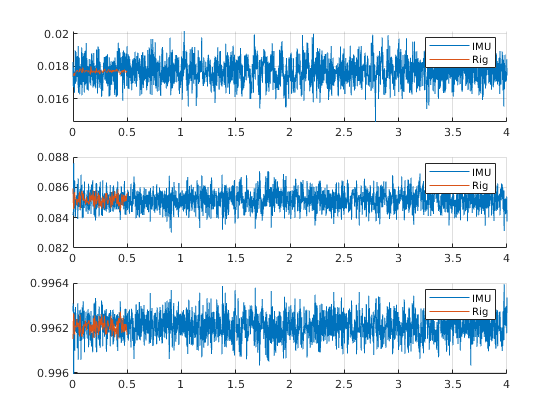

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

phase_roll_1 = data_IMU.start_and_stop(1,2):data_IMU.start_and_stop(2,1);

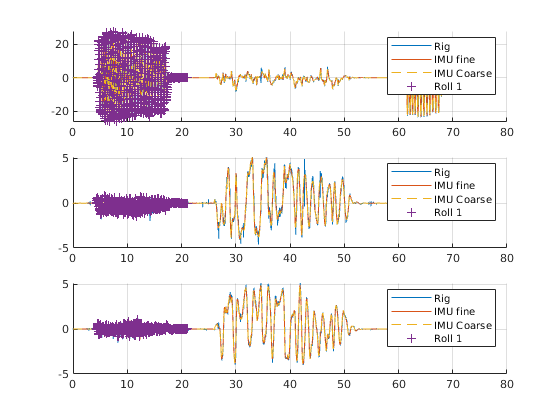

gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

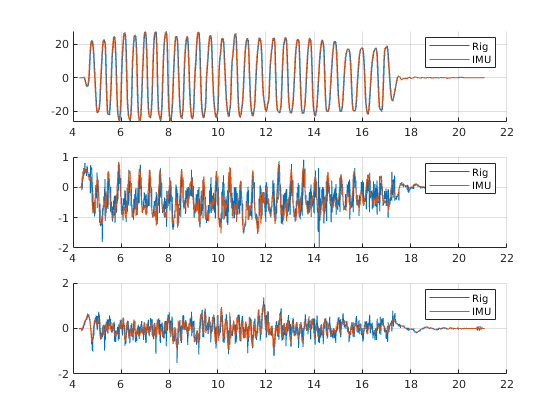


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         2135        2136        2137        2138        2139        2140        2141        2142        2143        2144        2145        2146        2147        2148        2149        2150        2151        2152        2153        2154        2155        2156        2157        2158        2159        2160        2161        2162        2163        2164        2165        2166        2167        2168        2169        2170        2171        2172        2173        2174        2175        2176        2177        2178        2179        2180        2181        2182        2183        2184


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 8403

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0


ans =    -0.0140    0.0021    0.0068    0.0095    0.0198    0.0643    0.0988    0.0884    0.0592    0.0258   -0.0228   -0.0544   -0.0503   -0.0377   -0.0216    0.0058    0.0243    0.0230    0.0179    0.0073   -0.0284   -0.0555   -0.0529   -0.0437   -0.0267    0.0211    0.0565    0.0428    0.0075   -0.0241   -0.0571   -0.0767   -0.0422    0.0275    0.0465    0.0410    0.0325    0.0186    0.0015    0.0013    0.0373    0.0667    0.0505    0.0144   -0.0034   -0.0117   -0.0155    0.0041    0.0435    0.0523


grid_search = t_shift_coarse + (-0.3:0.01:0.3);
cost_grid = arrayfun(cost, grid_search);


ans = 1.8206e+05

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1     -0.0708204       783241        initial
    2      0.0708204  2.54703e+06        golden
    3      -0.158359  4.51194e+06        golden
    4      -0.025922      4383.26        parabolic
    5     -0.0202131      2455.03        parabolic
    6     -0.0225651      391.695        parabolic
    7      -0.022601      391.234        parabolic
    8     -0.0226008      391.234        parabolic
    9     -0.0226008      391.234        parabolic
   10     -0.0226008      391.234        parabolic
   11     -0.0226008      391.234        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

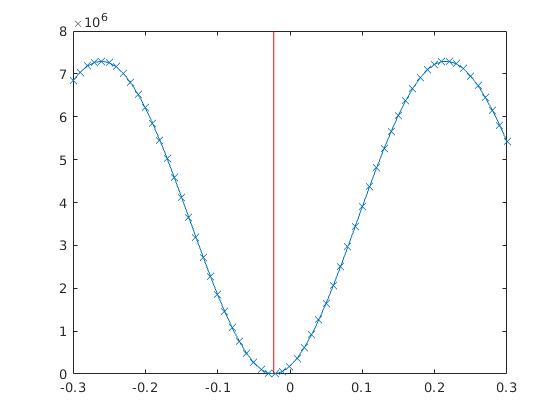

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


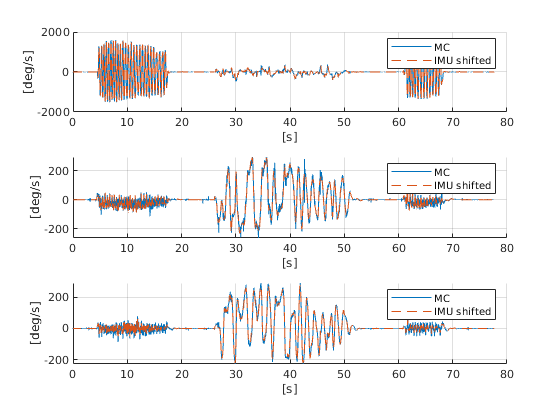

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time, "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
ylim([-1.35 0.71])

## Find release times

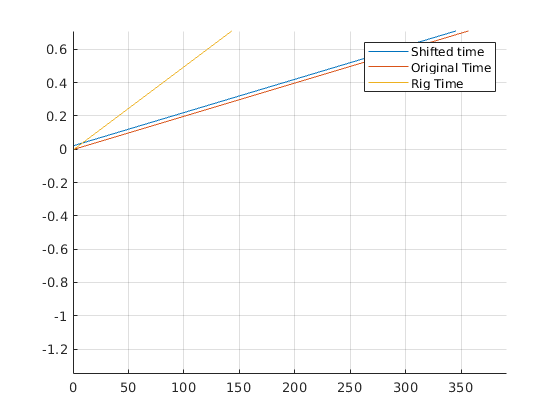



release_times_roll_2 = 61 + (0:19)*0.15
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 26 + (0:19)*1.2
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    61.0000   61.1500   61.3000   61.4500   61.6000   61.7500   61.9000   62.0500   62.2000   62.3500   62.5000   62.6500   62.8000   62.9500   63.1000   63.2500   63.4000   63.5500   63.7000   63.8500


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    26.0000   27.2000   28.4000   29.6000   30.8000   32.0000   33.2000   34.4000   35.6000   36.8000   38.0000   39.2000   40.4000   41.6000   42.8000   44.0000   45.2000   46.4000   47.6000   48.8000


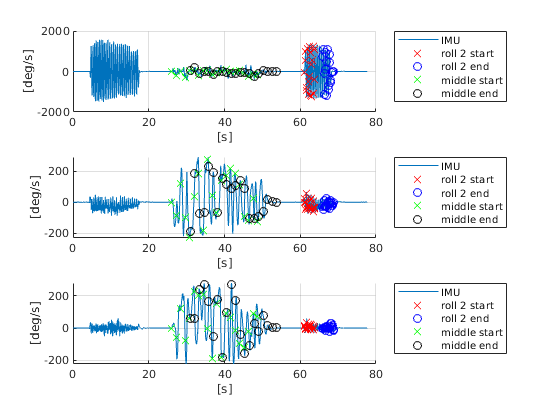


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

% save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt");
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");
% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 